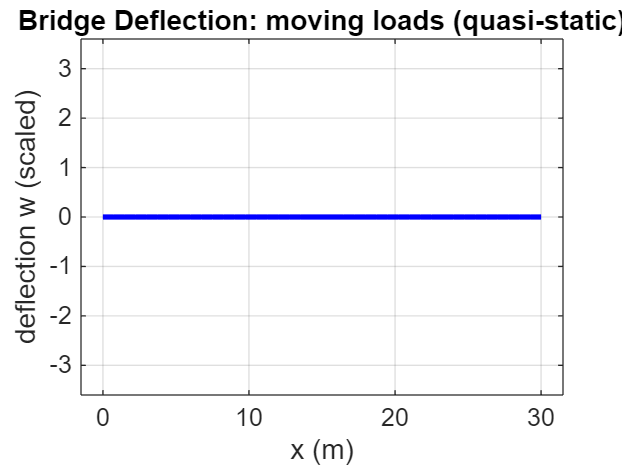

clear; clc; close all;

%% -------------------- User Inputs ---------------------------------------
L   = 30.0;          % span [m]
EI  = 3.0e10;        % flexural rigidity [N·m^2] (E*I)
Ne  = 40;            % number of beam elements (>=20 recommended)
v   = 15.0;          % vehicle speed [m/s] (~54 km/h)

% Axle loads (point forces, downward positive) and spacings
P_axle = [80e3, 120e3, 80e3];  % [N] (e.g., 80kN, 120kN, 80kN)
d_axle = [0, 3.5, 7.0];        % [m] spacing from first axle

t_end = (L + max(d_axle))/v;   % simulate until last axle leaves
dt    = 0.03;                  % time step [s] (animation + history)
scale = 50;                    % deformation plot scale factor (visual only)

%% -------------------- Mesh & DOFs ---------------------------------------
xnode = linspace(0,L,Ne+1).';
dx    = xnode(2)-xnode(1);
Nn    = Ne+1;
ndof  = 2*Nn;                  % per node: [w, theta]

% Assemble global stiffness
K = zeros(ndof);               % dense assembly is fine at this size
for e = 1:Ne
    Le = dx;
    ke = (EI/Le^3) * [ 12,   6*Le,  -12,   6*Le;
                       6*Le, 4*Le^2, -6*Le, 2*Le^2;
                      -12,  -6*Le,   12,  -6*Le;
                       6*Le, 2*Le^2, -6*Le, 4*Le^2 ];
    dof = [2*e-1 2*e 2*e+1 2*e+2];
    K(dof,dof) = K(dof,dof) + ke;
end

%% -------------------- Boundary Conditions (simply supported) ------------
% w(0)=0, w(L)=0; rotations free
fixed = [1, 2*Nn-1];               % DOF indices to fix (w at both ends)
free  = setdiff(1:ndof, fixed);

%% -------------------- Factorization for repeated solves ------------------
% Convert to sparse and factorize reduced matrix (FIXED)
K = sparse(K);                      % <- make sparse so LU returns P,Q
Kff = K(free,free);
[Lfac, Ufac, P, Q] = lu(Kff);       % <- 4 outputs valid for sparse

%% -------------------- Time March: move loads, solve quasi-static --------
t   = 0:dt:t_end;
mid = zeros(size(t));               % mid-span deflection history
env = -inf(Nn,1);                   % envelope (max |w(x)|)
envNeg = -inf(Nn,1); envPos = -inf(Nn,1);

w_dof_idx = 1:2:ndof;              % indices of w DOFs in global vector

% Animation setup
fig = figure('Color','w'); 
ax  = axes('Parent',fig); hold(ax,'on'); grid(ax,'on'); box(ax,'on');
axis(ax, [ -0.05*L, 1.05*L, -0.12*L, 0.12*L ]);
xlabel(ax,'x (m)'); ylabel(ax,'deflection w (scaled)');
title(ax,'Bridge Deflection: moving loads (quasi-static)');
plot(ax, xnode, zeros(size(xnode)),'k-','LineWidth',1); % baseline

h_def  = plot(ax, xnode, zeros(size(xnode)), 'b-', 'LineWidth',2);
h_load = plot(ax, nan, nan, 'ro', 'MarkerFaceColor','r');

for k = 1:numel(t)
    tk = t(k);
    x_lead = v*tk;
    x_loads = x_lead + d_axle;

    % Assemble nodal force vector (vertical forces only at w DOFs)
    F = zeros(ndof,1);
    for j = 1:numel(P_axle)
        xj = x_loads(j);
        if xj < 0 || xj > L, continue; end
        i = min(max(1, floor(xj/dx)+1), Nn-1);
        xi = xnode(i);
        xi_to_x = (xj - xi)/dx;     % in [0,1]

        Pi = P_axle(j) * (1 - xi_to_x);
        Pj = P_axle(j) * xi_to_x;

        F(2*i-1)     = F(2*i-1)     + Pi;   % w at node i
        F(2*(i+1)-1) = F(2*(i+1)-1) + Pj;   % w at node i+1
    end

    % Solve reduced system with sparse LU (FIXED)
    Ff = F(free);
    U  = zeros(ndof,1);
    U(free) = Q * (Ufac \ (Lfac \ (P * Ff)));

    w = U(w_dof_idx);

    % Update plots
    set(h_def,'XData',xnode,'YData', w*scale);
    inSpan = (x_loads>=0 & x_loads<=L);
    set(h_load,'XData', x_loads(inSpan), 'YData', zeros(1,nnz(inSpan)) );
    drawnow limitrate

    % Midspan and envelope
    mid(k) = interp1(xnode, w, L/2, 'linear');
    env    = max(env, abs(w));
    envPos = max(envPos, w);
    envNeg = max(envNeg, -w);
end


%% -------------------- Reports & Plots -----------------------------------
[max_def, imax] = max(env);
fprintf('Max |deflection| ≈ %.3f mm at x = %.2f m (quasi-static)\n', 1e3*max_def, xnode(imax));

Max |deflection| ≈ 5.020 mm at x = 15.00 m (quasi-static)


fprintf('Midspan min/max deflection over pass: [%.3f, %.3f] mm\n', 1e3*min(mid), 1e3*max(mid));

Midspan min/max deflection over pass: [0.000, 5.020] mm


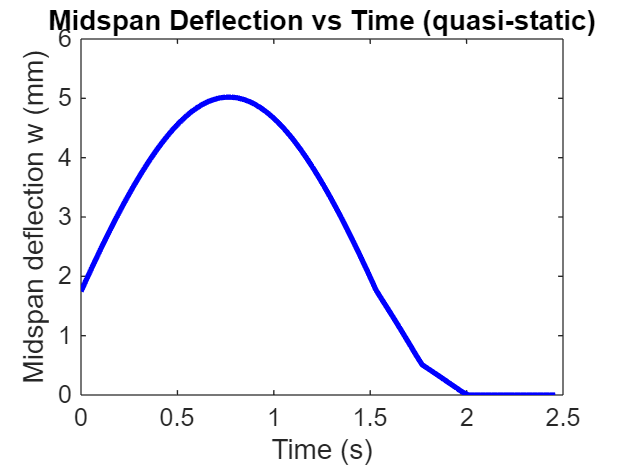


% Mid-span history
figure('Color','w'); grid on; box on;
plot(t, 1e3*mid, 'b-', 'LineWidth',2);
xlabel('Time (s)'); ylabel('Midspan deflection w (mm)');
title('Midspan Deflection vs Time (quasi-static)');

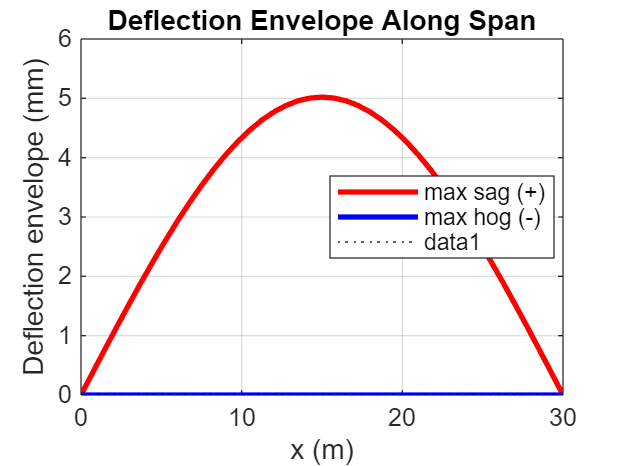


% Deflection envelope along span
figure('Color','w'); grid on; box on; hold on;
plot(xnode,  1e3*envPos, 'r-', 'LineWidth',2, 'DisplayName','max sag (+)');
plot(xnode, -1e3*envNeg, 'b-', 'LineWidth',2, 'DisplayName','max hog (-)');
plot(xnode, zeros(size(xnode)),'k:');
xlabel('x (m)'); ylabel('Deflection envelope (mm)');
title('Deflection Envelope Along Span');
legend('Location','best');